clear all; close all;

T_NDVI = readtable("T_Table_NDVI.csv");
T_NDVI = T_NDVI(2:end,3:22);
for i = 1:20 % because 20 years
    T_NDVI.Properties.VariableNames{i} = num2str(2001 + i);
end
clear i; 
T_NDVI = table2array(T_NDVI);
T_NDVI = T_NDVI(:);

T_EVI = readtable("T_Table_EVI.csv");
T_EVI = T_EVI(2:end,3:22);
for i = 1:20 % because 20 years
    T_EVI.Properties.VariableNames{i} = num2str(2001 + i);
end
clear i; 
T_EVI = table2array(T_EVI);
T_EVI = T_EVI(:);

T = [T_NDVI T_EVI];
T = [T  mean(T, 2)];

A = ~isnan(T(:,3));
T_EVI = T(:,1);
T_NDVI = T(:,2);

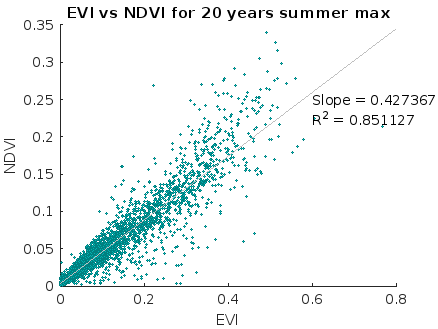

scatter(T_EVI(A), T_NDVI(A), 2,'MarkerEdgeColor',[0 .5 .5], ...
    'MarkerFaceColor',[0 .7 .7], ...
    'LineWidth',0.5);
hl = lsline;
B = [ones(size(hl.XData(:))), hl.XData(:)]\hl.YData(:);
Slope = B(2);
R = corrcoef(T_EVI(A), T_NDVI(A));
R_sq = R(1,2)^2;
xlabel("EVI"); ylabel("NDVI");
title("EVI vs NDVI for 20 years summer max");
text(0.6,0.25, sprintf('Slope = %f', Slope))
text(0.6,0.225, sprintf('R^2 = %f', R_sq))

saveas(gcf,'Figure_18.pdf')